# lTEMPLATE FOR DATA LABEL

Version: 2.0

Date: 1/08/2022 

## EXPLANATION:

 At the beginning of each experiment you have to start from the STEP 1.

For the second suture or more from the same experiment, you have to start from the STEP 4 for each suture.

___________________

## STEP 1:   INITIALIZE THE PROJECT WITH THE NUMBER OF THE EXPERIMENT

- **Write the number of the experiment (line 8)**

% DO NOT CHANGE %--------------------
clc
clear all
%-----------------------------------


%%  WRITE HERE THE NUMBER OF THE EXPERIMENT   %%
experimiento = 1;  % <-----------------
%%%%%%%

    **2. Run this section (one click on the blue lines on the left side of the number of the lines)**

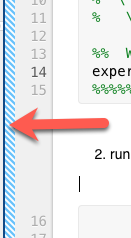

Do not change anything else in this step

% DO NOT CHANGE %-----------------------
carpetaExp = sprintf('exp%d',experimiento);
RawFiles = strcat(pwd,'\',carpetaExp,'\RawFiles');
SutureFiles = strcat(pwd,'\',carpetaExp);
mkdir(SutureFiles,'Sutures');

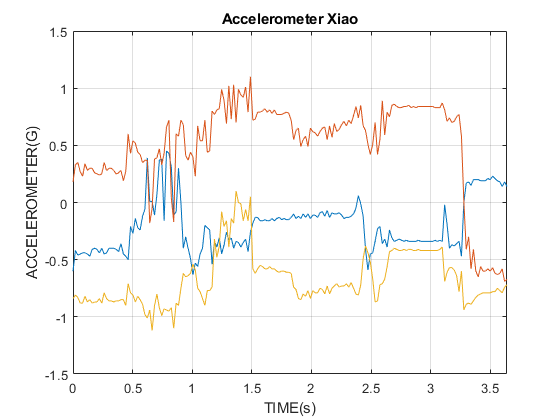

xiao_table = fullfile(RawFiles, sprintf('normal3 overpucture'));
xiao_Signals = readtable(xiao_table);
f = 50;
T = 1/50;

figure()
total_time1_xiao = length(xiao_Signals.ACX)*T;
time_vector1_xiao = linspace(0,total_time1_xiao,length(xiao_Signals.ACX));
plot(time_vector1_xiao,xiao_Signals.ACX,time_vector1_xiao,xiao_Signals.ACY,time_vector1_xiao,xiao_Signals.ACZ)
title ('Accelerometer Xiao')
ylabel('ACCELEROMETER(G)')
xlabel('TIME(s)')
xlim tight
grid on

%-------------------------------------







## _____________________   START FROM HERE FOR EACH SUTURE

__________

## STEP 4:  FIND THE KEY POINTS FOR THE SUTURE

- **Wirte the number of the SUTURE**

The number of the suture starts with 1 for the first one of each experiment

%%%%% WRITE THE SUTURE NUMBER FROM THIS EXPERIMENT %%%%%%%
sutura = 1; % <-----------------

%%%%%% IGNORE THIS LINE - DONT CHANGE ANYTHING%%%%
% load VarToload.mat;

    **    3. Watch the video and note the time where the important things happen**

%%%%% WRITE THE RANGE OF VALUES HERE %%%%%%%
% .. = [MINUTE SECOND]


% WRITE THE TIME FOR THE BEGINNING OF THE SUTURE (THE PROCEDURE)
inicioSutura = [0 0.2];

% WRITE THE TIME WHEN THE NEEDLE IS INSERTED
inicioAguja = [0 1.0];
finalAguja = [0 1.9];


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% VUELTAS %%%%%%%%%%%%%%%%%%%%%
% YOU CAN ADD OR REMOVE THE PACKAGE OF LINES IF IT'S NECESSARY 

%--
numVuelta = 1;
inicioVueltas(numVuelta,:) = [0 2.0];
finalVueltas(numVuelta,:) = [0 2.9];
orientacionVueltas(numVuelta) = 1; % 0 'abajo' o 1 'arriba' segun la orientacion;
%--

%--
numVuelta = 2;
inicioVueltas(numVuelta,:) = [0 3.0];
finalVueltas(numVuelta,:) = [0 3.80];
orientacionVueltas(numVuelta) = 0;
%--

% %--
% numVuelta = 3;
% inicioVueltas(numVuelta,:) = [5 28.23];
% finalVueltas(numVuelta,:) = [5 28.65];
% orientacionVueltas(numVuelta) = 1; % 0 'abajo' o 1 'arriba' segun la orientacion;
% %--


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% FIN VUELTAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
finalSutura = [0 3.5];
tiempofinalsutura = ConvTime(finalSutura);


**4. Run this section (one click on the blue lines on the left side of the number of the lines)**

**5. CHECK THE GRAPH WITH COLORS IF EVERYTHING IS FINE**

DO NOT CHANGE FROM HERE

% DO NOT CHANGE %-----------------------
%%%%%%%%%%%%%%%%% no cambiar guarado de variables %%%%%%%%%%%%%%%%
SutureFolder = fullfile(strcat(SutureFiles,'\Sutures'),sprintf('Suture%d',sutura));
mkdir(SutureFolder);

mkdir(SutureFolder, "log")

mkdir(SutureFolder, "img")

mkdir(SutureFolder, "Negative")

mkdir(SutureFolder, "Positive")

mkdir(strcat(SutureFolder,'\Positive'),"AgujaEntraSale")

mkdir(strcat(SutureFolder,'\Positive'),"Vueltas")

mkdir(strcat(SutureFolder,'\Positive'),"VueltasAdelante")

mkdir(strcat(SutureFolder,'\Positive'),"VueltasAtras")

for w=1:length(orientacionVueltas)
    if orientacionVueltas(w) == 0
        [VueltasAbajo_APL] = Guardado(inicioVueltas(w,:),finalVueltas(w,:),xiao_Signals);
        VueltasAbajo = fullfile(strcat(SutureFolder,'\Positive\VueltasAtras'), sprintf('Range_VueltasAtras%d_Suture%d_exp%d.mat',w,sutura,experimiento));
        save(VueltasAbajo,"VueltasAbajo_APL","-mat");
    else 
        [VueltasArriba_APL] = Guardado(inicioVueltas(w,:),finalVueltas(w,:),xiao_Signals);
        VueltasArriba = fullfile(strcat(SutureFolder,'\Positive\VueltasAdelante'),sprintf('Range_VueltasAdelante%d_Suture%d_exp%d.mat',w,sutura,experimiento));
        save(VueltasArriba,"VueltasArriba_APL","-mat");
    end
end

Error using Guardado (line 2)
Row index exceeds table dimensions.

[Positive_Aguja_APL] = Guardado(inicioAguja,finalAguja,xiao_Signals);
Aguja = fullfile((strcat(SutureFolder,'\Positive\AgujaEntraSale')),sprintf('Positive_Aguja_Suture%d_exp%d.mat',sutura,experimiento));
save(Aguja,'Positive_Aguja_APL');

%%%% guarda el rango de inicio y final de todas las vueltas incluyendo los negativos %%%%%
[Vueltas_APL] = Guardado(inicioVueltas(1,:),finalVueltas(length(finalVueltas),:),xiao_Signals);
Vueltas = fullfile(strcat(SutureFolder,'\Positive\Vueltas'), sprintf('Range_Vueltas_Suture%d_exp%d.mat',sutura,experimiento));
save(Vueltas,"Vueltas_APL","-mat");
%%% guarda el rango desde el inicio de la sutura al final %%%
[SutureRange_APL] = Guardado(inicioSutura,finalSutura,xiao_Signals);
Range_Suture = fullfile(strcat(SutureFolder,'\log'), sprintf('Range_Suture%d_exp%d.mat',sutura,experimiento));
save(Range_Suture,"SutureRange_APL","-mat");
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%% NO MODIFICAR %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% conversion a segundo y guardado de variables
inicios=[];
finales = [];
for n=2:length(orientacionVueltas)+1
    for j=1:n-1
    tiempo = ConvTime(inicioVueltas(j,:));
    inicios(n) = tiempo;  
    end
end
finales(1) = ConvTime(inicioSutura);
inicios(1) = ConvTime(inicioAguja);
finales(2) = ConvTime(finalAguja);
sizeOfinicios = length(inicios);             
inicios(sizeOfinicios+1) = ConvTime(finalSutura);
for n=3:length(finalVueltas)+2
    for j=1:n-2
    tiempo = ConvTime(finalVueltas(j,:));
    finales(n) = tiempo;
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% Grafica para comprobar que los puntos quedaron bien marcado y guardar
%%%% negativos %%%%%%
figure()
for n=1:numel(inicios)
    a_num = inicios(n);
    b_num = finales(n);
    [SutureRange_Negative_APL] = GuardadoNegativo(a_num,b_num,xiao_Signals);
    Range_Suture_negative = fullfile(strcat(SutureFolder,'\Negative'), sprintf('Range_Suture%d_Negative%d_exp%d.mat',sutura,n,experimiento));
    save(Range_Suture_negative,"SutureRange_Negative_APL","-mat");
end    
z=GuardarGraficasPDF(xiao_Signals,time_vector1_xiao,inicios,finales,SutureFolder);
AllVar = fullfile(strcat(SutureFolder,'\log'), sprintf('AllVar_Suture%d_exp%d.mat',sutura,experimiento));
save(AllVar,"-mat");
Array_iniFin = fullfile(strcat(SutureFolder,'\log'), sprintf('Arrays_IniFin_Suture%d_exp%d.mat',sutura,experimiento));
save(Array_iniFin,"-mat");